clear all
clc

% 初始参数
t = [0:0.001:24] % 代表从0点至24点

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


d_n = 180 % 天数（0-365）

d_n = 180

D_n = [1:1:365]'

D_n =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


I_SC = 1367; % 地外太阳辐射强度常数
r_0 = 149597890; % 平均日地距离常数
phi = 30; % 纬度
epislon = 1/298.256; % 地球扁率
tau = 1; % 投射系数 无量纲

% 计算单位太阳辐射强度
alpha_day = 2 * pi * (d_n - 4)/365; % 天角数
r = r_0 * (1 - epislon^2) / (1 + epislon * cos(alpha_day)); % 日地距离
I_0n = I_SC * (r_0 / r)^2; % 地外太阳辐射强度
omega = pi - (pi * t / 12); % 时角
delta = (23.45 * pi / 180) * sind(360 * (284 + d_n) /365); % 太阳倾斜角
theta = pi / 2 - acos(sind(phi) * sin(delta) + cosd(phi) * cos(delta) * cos(omega)); % 天顶角

P_S = max(I_0n * tau * sin(theta), 0) % 单位面积太阳辐射强度

P_S = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


E_S = cumtrapz(t, P_S) % 单位面积太辐射总能量

E_S = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_AS = E_S(end) / 24

P_AS = 488.5490

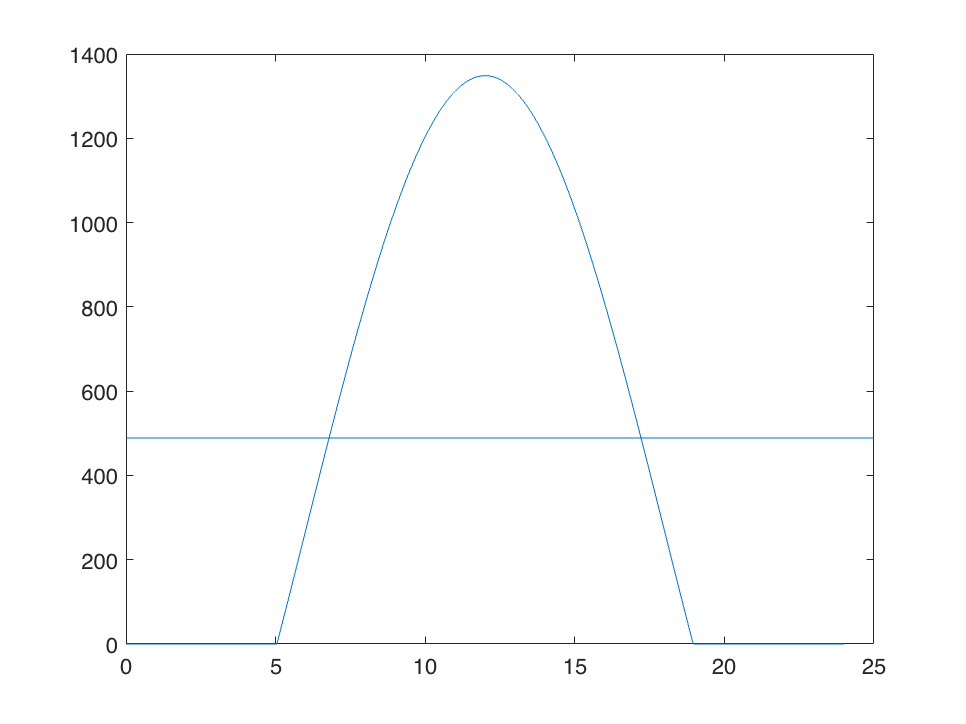


% Plot
plot(t, P_S)
hold on
refline([0 P_AS])
hold off

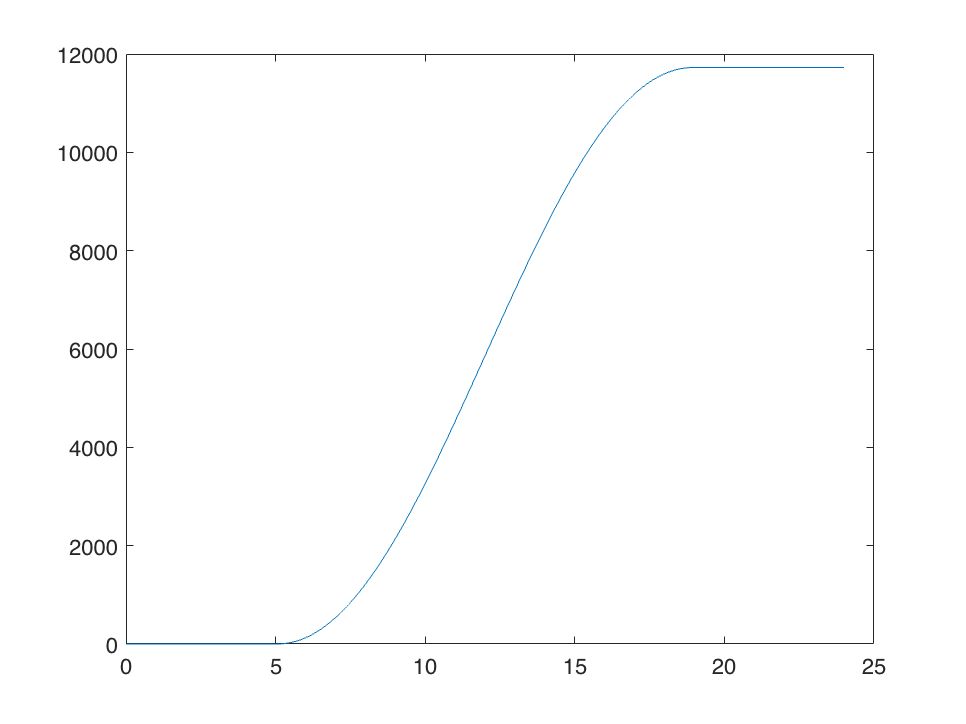

plot(t, E_S)

% 全年太阳辐射强度图谱
D_alpha_day = 2 * pi * (D_n - 4)/365; % 天角数
D_r = r_0 * (1 - epislon^2) ./ (1 + epislon .* cos(D_alpha_day)); % 日地距离
D_I_0n = I_SC .* (r_0 ./ D_r).^2; % 地外太阳辐射强度
D_omega = pi - (pi * t / 12); % 时角
D_delta = (23.45 * pi / 180) .* sind(360 * (284 + D_n) ./365); % 太阳倾斜角
D_theta = pi / 2 - acos(sind(phi) * sin(D_delta) + cosd(phi) * cos(D_delta) * cos(D_omega)); % 天顶角

D_P_S = max(D_I_0n * tau .* sin(D_theta), 0) % 单位面积太阳辐射强度

D_P_S = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

D_E_S = cumtrapz(t, D_P_S, 2) % 单位面积太辐射总能量

D_E_S = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

D_P_AS = D_E_S(:,end) / 24

D_P_AS =   225.2373
  225.8194
  226.4495
  227.1276
  227.8532
  228.6263
  229.4464
  230.3134
  231.2268
  232.1863


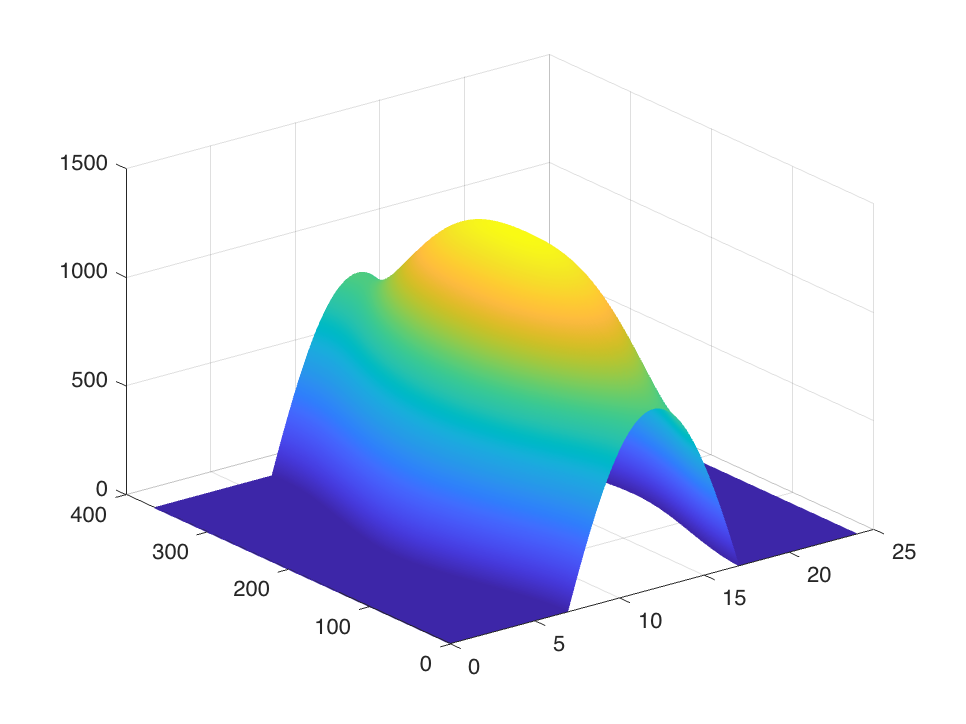


% Plot3
mesh(t, D_n, D_P_S)

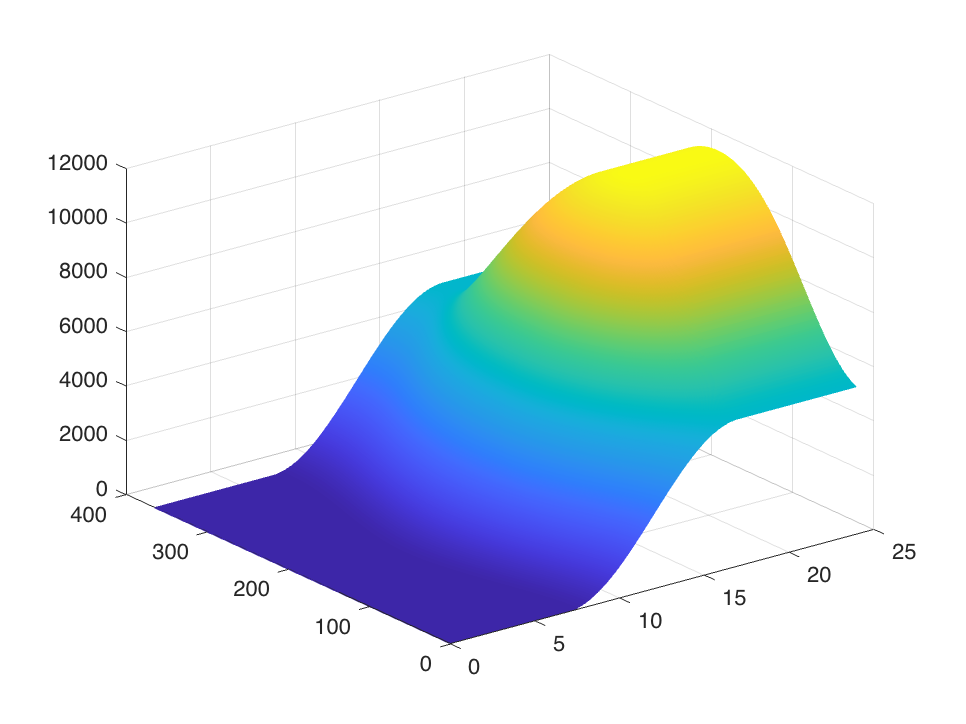

mesh(t, D_n, D_E_S)

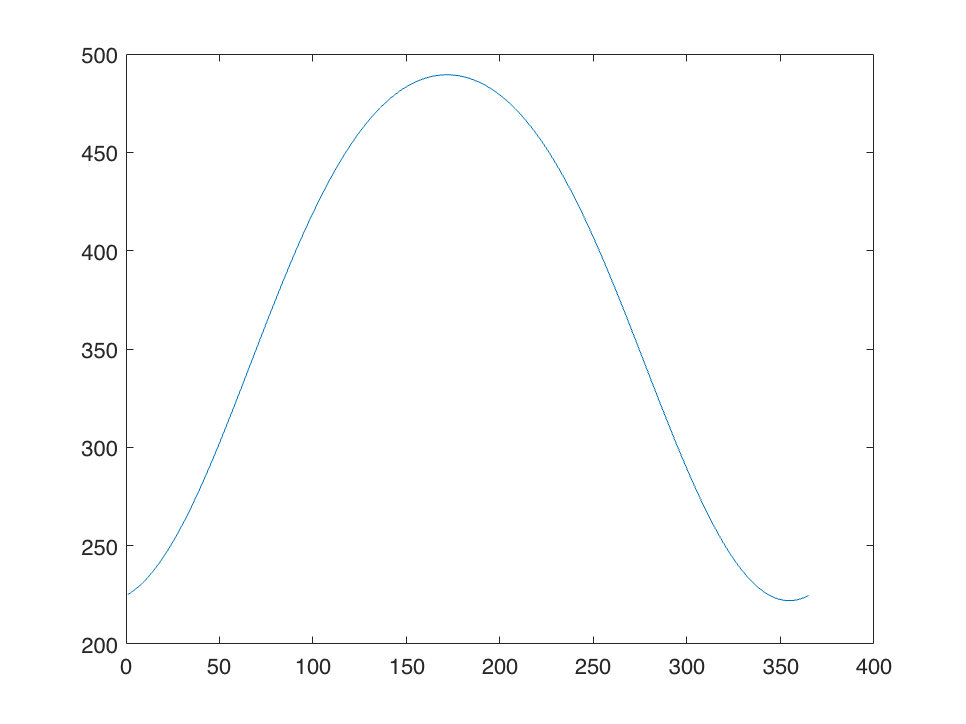

plot(D_n, D_P_AS)

% 生成用于Simulink的数据
solar_radiation = [t'*3600, P_S']

solar_radiation = 	1.0e+04 *

         0         0
    0.0004         0
    0.0007         0
    0.0011         0
    0.0014         0
    0.0018         0
    0.0022         0
    0.0025         0
    0.0029         0
    0.0032         0
